# Efficiency and Power Losses Maps Generation

## Introduction

The goal is to generate an efficiency and power losses map based on results of simulations. For this particular converter, here is how the maps look like:

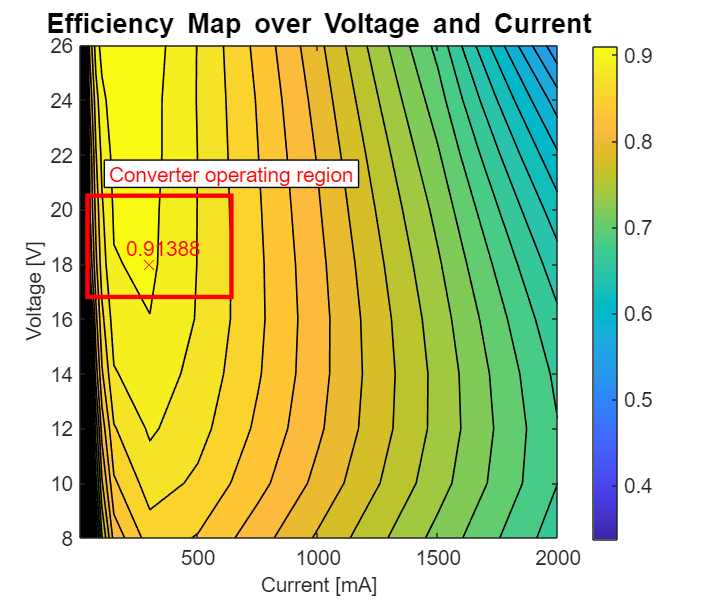

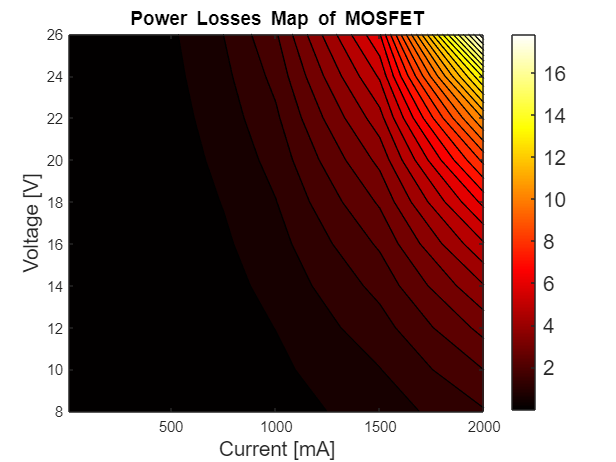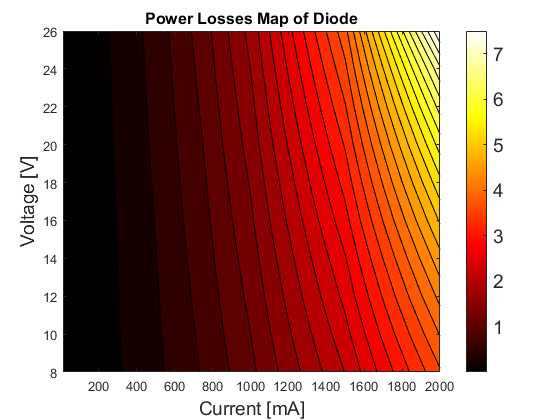

In order to evaluate the converter efficiency and power losses, and generate a map which has voltage and current as inputs, we need to create a dedicated test harness that will regulate the voltage to a specific setpoint (closed loop). For each voltage setpoint, we need additional simulation varying the load resistor to make sure the right amount of current flows into the load.

Let's start by opening up  the model:

bdclose all
% OpenModelAtEfficiencyHarnessLevel;
% DCDC_SEPIC_Efficiency_Analysis TO_DELETE
Model_Name ='DCDC_SEPIC_Efficiency_Analysis';
open_system(Model_Name);

Because we are sweeping over multiple points, and we are looking for ohmic losses mostly, we can use idealistic components to speed up the analysis. Detailed power losses using Physical Devices model can be done separately for few operating points.

set_param([Model_Name,'/SEPIC_Circuit/Diode'],'LabelModeActivechoice','PiecewiseLinear');
set_param([Model_Name,'/SEPIC_Circuit/MOSFET'],'LabelModeActivechoice','IdealMOSFET');

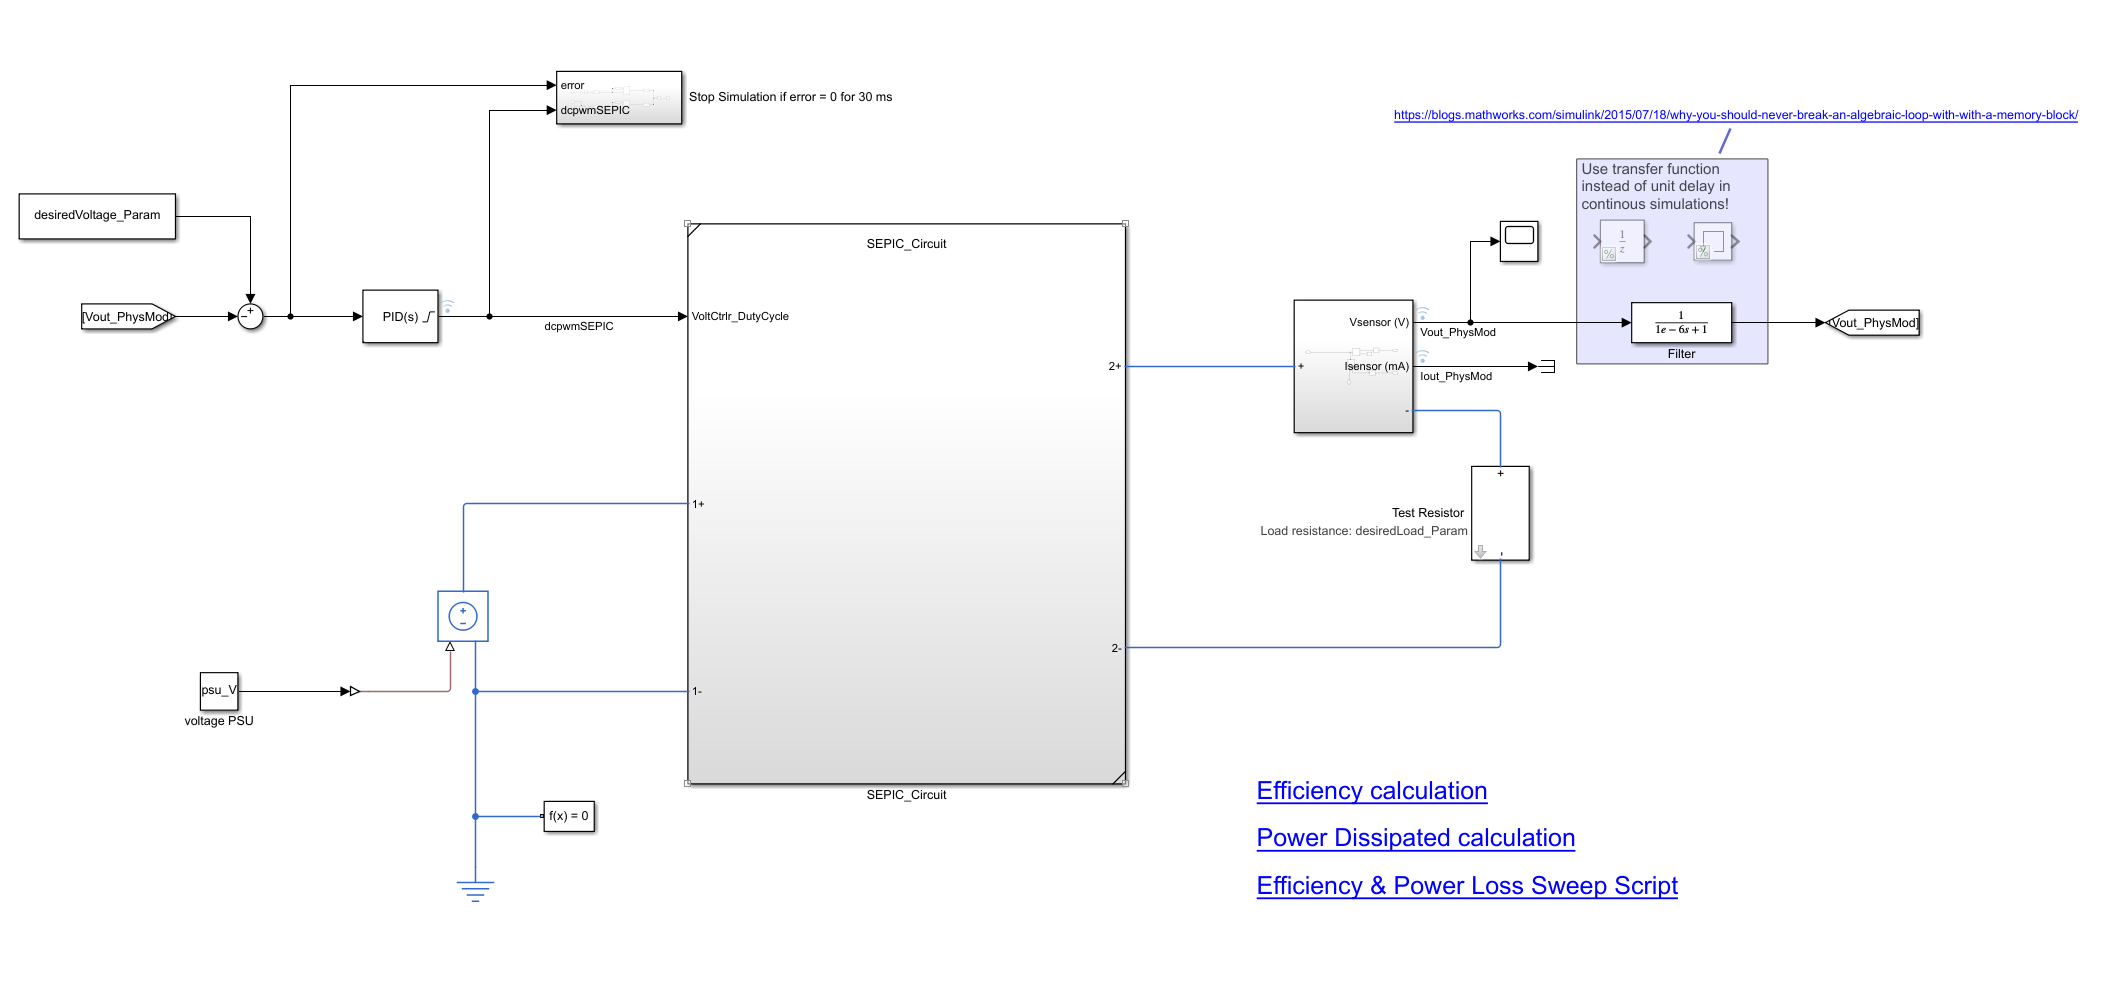

### Comments 

This is an external model referencing the SEPIC_Circuit subsystem. Since the goal is to investigate efficiency and power losses, an average model cannot be used.

The model has a simple PID, tuned with Simulink Control Design & System Identification Toolbox to deliver a fast response (see [Control Design and Tuning](matlab:open('./ControlDesignAndTuning.mlx'))). The model needs to settle at target voltage as quickly as possible, so robustness or overshoots are not important: is just an analysis, not parameter for the final operation. In order to break the algebraic loop a very fast continous transfer function is used, see blog post here:

[https://blogs.mathworks.com/simulink/2015/07/18/why-you-should-never-break-an-algebraic-loop-with-with-a-memory-block/](https://blogs.mathworks.com/simulink/2015/07/18/why-you-should-never-break-an-algebraic-loop-with-with-a-memory-block/)

Two parameters should be set: the desired voltage, and the resistance in the test resistor. The resistance must be chosen so that a certain current is flowing at the desired voltage. Example for a single simulation:

Voltage_Test_Single = 18;% V
Curr_Test_Single = 500;   % mA

desiredLoad_Param = Voltage_Test_Single/(Curr_Test_Single*0.001); % Resistance in Ohm
desiredVoltage_Param = Voltage_Test_Single; % Voltage in Volt
desired_dcMax = 0.95;
desiredCurrent_Param = Curr_Test_Single;


The model has a subsystem triggerint a simulation stop when the signal has settled for 30 ms or if the signal out of the PID controller (the duty cycle) is at the upper level of saturation for too long:

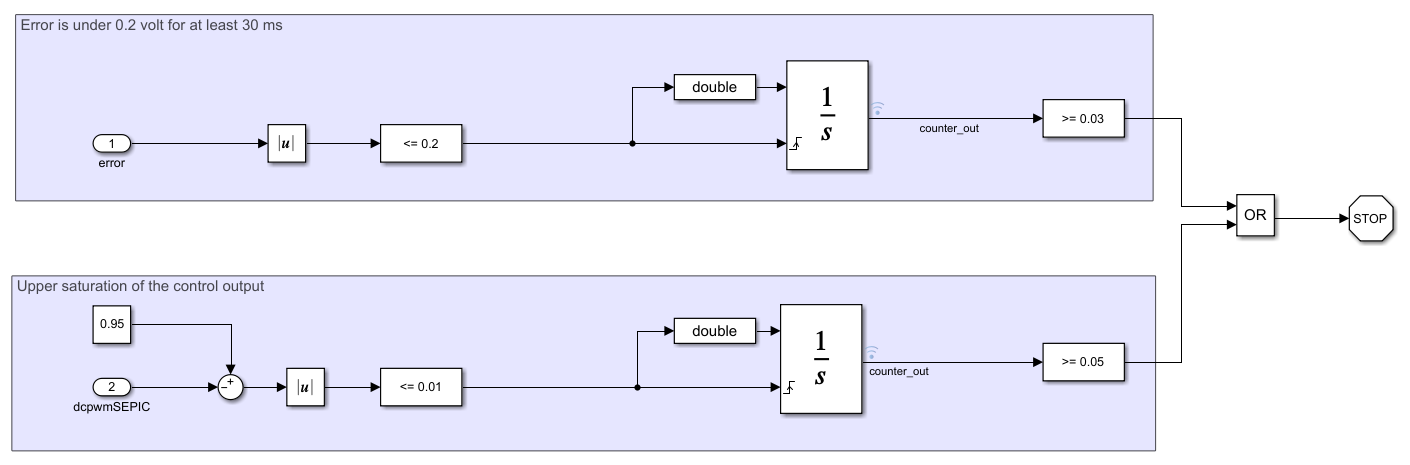

### Converter stability and voltage gain

The ideal SEPIC voltage gain formula is:


$$V_o =\frac{D}{1-D}V_{\textrm{in}}$$


But this equation is not valid for a physical system, which includes resistive losses of internal resistances. A more realistic formula is:


$$V_o =\frac{V_{\textrm{in}} }{\frac{1-D}{D}+\frac{D*r_{\textrm{L1}} }{R_{\textrm{load}} *\left(1-D\right)}+\frac{\left(2D-1\right)*r_{\textrm{C1}} }{R_{\textrm{load}} }-\frac{\left(1-D\right)*r_{\textrm{L2}} }{D*R_{\textrm{load}} }}$$


This function has been implemented as local function at the bottom of this script. If we sweep over the duty cycle we obtain the Vout curve:

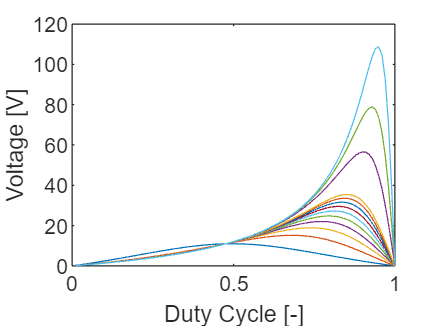

dc_vec=0:0.01:1;
res_vec=[0.5:1:10,25,50,100];
vOut_vec=[];
for i=1:length(res_vec)
    for k=1:length(dc_vec)  
        %Calculating true R load because of power resistor R1 in parallel:
        R_load_Tot(i) = PR1_Res*res_vec(i)/(PR1_Res+res_vec(i));

        %Vout based on voltage gain formula:
        vOut_vec(k,i)=SEPIC_VoltageGain_Limit(psu_V,dc_vec(k),R_load_Tot(i),L1_Res,L2_Res,0);
    end
    [maxVout(i) Idx]=max(vOut_vec(:,i));
    dcMax(i) = dc_vec(Idx);
end
plot(dc_vec,vOut_vec)
xlabel('Duty Cycle [-]')
ylabel('Voltage [V]')

Very intersting is to observe the DC value where the peak occurs, based on the various load resistance

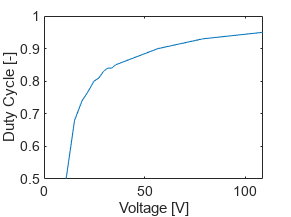

plot(maxVout,dcMax)
xlabel('Voltage [V]')
ylabel('Duty Cycle [-]')

The value at which peak occurs is very important for control purposes. If you are using a PID controller, and you don't saturate on the peak DC value, there is a possibility that the controller starts outputting DC value on the right of the peak (eg >95% DC etc). In this region, increasing DC would lower the voltage, stopping de facto the PID controller to work, unless countermeasures are taken. The controller expect to increase voltage by increasing DC, and this non-linearity changes completely the system behaviour.

The easiest way to counter this peak is to limit DC output of the PID controller to the max DC value per load. We can implement this in Simulink by reading the current and voltage feedback and using it to estimate the equivalent load resistance and therefore through an interpolated polymonial, the max DC value.

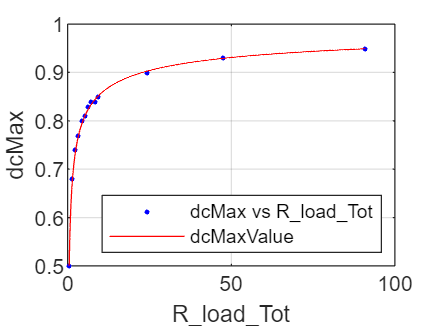

%% Fit: 'dcMaxValue'.
[xData, yData] = prepareCurveData( R_load_Tot, dcMax );

% Set up fittype and options.
ft = fittype( 'power2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.552207650210197 0.193950478588422 -0.0248862364405307];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'dcMaxValue' );
h = plot( fitresult, xData, yData );
legend( h, 'dcMax vs R_load_Tot', 'dcMaxValue', 'Location', 'southeast', 'Interpreter', 'none' );
% Label axes
xlabel( 'R_load_Tot', 'Interpreter', 'none' );
ylabel( 'dcMax', 'Interpreter', 'none' );
grid on


fitresult

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =     -0.3963  (-0.4111, -0.3816)
       b =     -0.3861  (-0.4079, -0.3643)
       c =       1.018  (1.005, 1.032)

The fit result has been then integrated as a new custom function which takes both resistance Load and PR1 in, calculates the total equivalent resistance, integrate upper and lower limits to the duty cycle:

desired_dcMax=customFit(desiredLoad_Param,PR1_Res,fitresult)

desired_dcMax = 0.9176

### Single simulation considerations

Let's simulate twice, while logging all points. Once we use the correct max value for duty cycle, as calculated with the customFit function, and once we put no upper limit:

set_param(Model_Name,'SimscapeLogLimitData','off');

%With DC limited
desired_dcMax=customFit(desiredLoad_Param,PR1_Res,fitresult);
out_fullLog=sim(Model_Name);

%Without DC limit
desired_dcMax=1;
out_fullLog_noLim=sim(Model_Name);

Voltage:

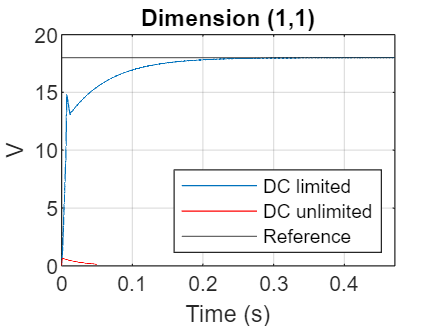

plot(out_fullLog.simlog.Test_Resistor.TestResistor_Load.Resistor.v.series);
hold on
plot(out_fullLog_noLim.simlog.Test_Resistor.TestResistor_Load.Resistor.v.series.time,out_fullLog_noLim.simlog.Test_Resistor.TestResistor_Load.Resistor.v.series.values,'r');
hold on
yline(desiredVoltage_Param);
legend('DC limited','DC unlimited','Reference','Location','southeast')

It can be appreciated that without a proper duty cycle limitation for the upper value, the controller will increase at the beginning of the step to values on the right side of the "peak", where an increase of duty cycle means a decrease of voltage. This makes the PID effectively works against the error signal and cannot bring the system to the desired voltage.

The signals converge and after 30 ms of low error versus the reference and the simulation is stopped automatically. In order to retrieve only the average power losses and efficiency for a certain operating point, and without considering the initial settling time, it is possible to save on resources and log only the final 5000 points of the simulation, example:

set_param(Model_Name,'SimscapeLogLimitData','on');
set_param(Model_Name,'SimscapeLogDataHistory',5000);
desired_dcMax=customFit(desiredLoad_Param,PR1_Res,fitresult);

out_partialLog=sim(Model_Name);

Voltage:

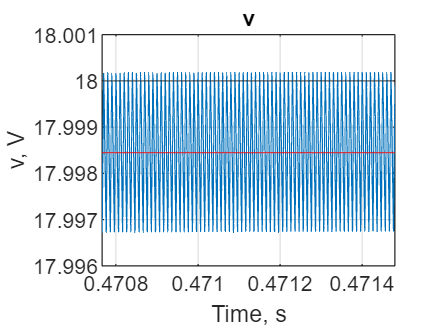

plot(out_partialLog.simlog.Test_Resistor.TestResistor_Load.Resistor.v);
hold on
yline(rms(out_partialLog.simlog.Test_Resistor.TestResistor_Load.Resistor.v.series.values),'r')
hold on
yline(desiredVoltage_Param);

Current:

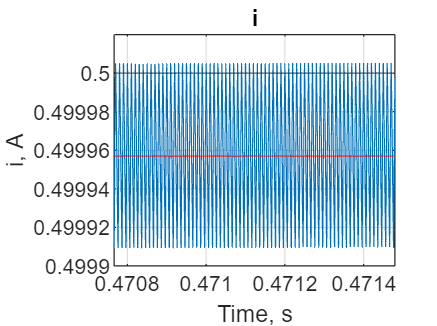

plot(out_partialLog.simlog.Test_Resistor.TestResistor_Load.Resistor.i);
hold on
yline(rms(out_partialLog.simlog.Test_Resistor.TestResistor_Load.Resistor.i.series.values),'r')
hold on
yline(Curr_Test_Single/1000);

The rms is less than 0.01 V away from the target voltage.

Let's compare the power losses and the efficiency for both full and partial log:

MOSFET Power Losses:

full_log_MOSFET_PowerLosses=ee_getPowerLossSummary(out_fullLog.simlog.SEPIC_Circuit.MOSFET.IdealMOSFET.MOSFET)

full_log_MOSFET_PowerLosses = 1×2 table
    LoggingNode    Power 
    ___________    ______

    {'MOSFET'}     1.4172


partial_log_MOSFET_PowerLosses=ee_getPowerLossSummary(out_partialLog.simlog.SEPIC_Circuit.MOSFET.IdealMOSFET.MOSFET)

partial_log_MOSFET_PowerLosses = 1×2 table
    LoggingNode     Power 
    ___________    _______

    {'MOSFET'}     0.26796


Diode Power Losses:

full_log_Diode_PowerLosses=ee_getPowerLossSummary(out_fullLog.simlog.SEPIC_Circuit.Diode)

full_log_Diode_PowerLosses = 1×2 table
                          LoggingNode                            Power 
    ________________________________________________________    _______

    {'Diode.Piecewise_Linear_Diode.Piece_Wise_Linear_Diode'}    0.71316


partial_log_Diode_PowerLosses=ee_getPowerLossSummary(out_partialLog.simlog.SEPIC_Circuit.Diode)

partial_log_Diode_PowerLosses = 1×2 table
                          LoggingNode                           Power 
    ________________________________________________________    ______

    {'Diode.Piecewise_Linear_Diode.Piece_Wise_Linear_Diode'}    0.5407


Efficiency:

full_log_Efficiency=ee_getEfficiency('Load',out_fullLog.simlog)

full_log_Efficiency = 67.4476

partial_log_Efficiency=ee_getEfficiency('Load',out_partialLog.simlog)

partial_log_Efficiency = 89.3629

And finally, let's calculate the efficiency manually by using input and output power. In this application, input power is provided by the PSU represented as a controllable voltage source. Load is twofold: the main load, in this case modeled as a resistor, together with a power resistor PR1 shipping with the true hardware board. This power resistor is used to bring the capacitor to 0 when powered off without a connected load, enhancing safety. The power resistor PR1 is modeled in the SEPIC circuit itself.

power_Load=rms(out_partialLog.simlog.Test_Resistor.TestResistor_Load.Resistor.i.series.values.*out_partialLog.simlog.Test_Resistor.TestResistor_Load.Resistor.v.series.values)

power_Load = 8.9984

power_Load_fcn=ee_getPowerLossSummary(out_partialLog.simlog.Test_Resistor.TestResistor_Load.Resistor)

power_Load_fcn = 1×2 table
    LoggingNode     Power 
    ____________    ______

    {'Resistor'}    8.9985


power_PR1 = rms(out_partialLog.simlog.SEPIC_Circuit.PR1_Load.Resistor.i.series.values.*out_partialLog.simlog.SEPIC_Circuit.PR1_Load.Resistor.v.series.values)

power_PR1 = 0.3239

power_PR1_fcn=ee_getPowerLossSummary(out_partialLog.simlog.SEPIC_Circuit.PR1_Load.Resistor)

power_PR1_fcn = 1×2 table
    LoggingNode      Power 
    ____________    _______

    {'Resistor'}    0.32395


power_PSU = rms(out_partialLog.simlog.Controlled_Voltage_Source.i.series.values.*out_partialLog.simlog.Controlled_Voltage_Source.v.series.values)

power_PSU = 10.4681


hand_calculated_efficiency=(power_Load+power_PR1)/power_PSU*100

hand_calculated_efficiency = 89.0555

The power losses calculated using the shipping function or by hand have the same result. The efficiency calculated by hand is smaller than the results of the ee_getEfficiency function: 89.0555% vs 89.3629%. This happens because the ee_getEfficiency function works with the internal power_dissipated variable, used as well by the ee_getPowerLossSummary funciton. This internal variable tracks only ohmic losses and does not track switching losses.

Hence, to truly calculate the overall efficiency, is still better to calculate the efficiency by hand by calculating the overall power coming from the PSU (which needs an "hand" calculation involving rms, voltage and current) and the power dissipated by the two loads.

### Adding calculation as post sim callback:

In order to generate the map, for each simulation only a couple of values are needed: MOSFET and Diode powr losses, as well as efficiency. Power electronics simulations tend to generate sizable vectors because of the high frequency used in PWM that drive simulation steps in the solver. This can easily create GBs of simulation results which can slow down workflows. One way to mitigate it is to reduce the number of points (see above) and then use the vector in postprocessing in order to extract the relevant feature and save then only one number instead of whole vectors.

set_param(Model_Name,'SimscapeLogLimitData','on');
set_param(Model_Name,'SimscapeLogDataHistory',5000);
set_param(Model_Name,'StopTime','2');
save_system(Model_Name,'SaveDirtyReferencedModels','on');

in = Simulink.SimulationInput(Model_Name);
in = in.setPostSimFcn(@(x) customPostSim(x));
in = in.setVariable('desiredVoltage_Param',Voltage_Test_Single);
in = in.setVariable('desiredLoad_Param',Voltage_Test_Single/(Curr_Test_Single*0.001));
in = in.setVariable('desired_dcMax',customFit(Voltage_Test_Single/(Curr_Test_Single*0.001),PR1_Res,fitresult));
in = in.setVariable('desiredCurrent_Param',Curr_Test_Single);

outSingle = sim(in);


### Results

disp(['Final Operating Point: ',num2str(outSingle.V_rms),' V & ',num2str(outSingle.I_rms*1000),' mA'])

Final Operating Point: 17.9984 V & 499.9569 mA



disp(['Efficiency: ',num2str(outSingle.Efficiency*100),' %'])

Efficiency: 89.0558 %


disp(['Diode power losses: ',num2str(outSingle.power_Diode),' W'])

Diode power losses: 0.5407 W


disp(['MOSFET power losses: ',num2str(outSingle.power_MOSFET),' W'])

MOSFET power losses: 0.26796 W


disp(['Load power (including PR1): ',num2str(outSingle.power_Load_tot),' W'])

Load power (including PR1): 9.3224 W


disp(['PSU power: ',num2str(outSingle.power_PSU),' W'])

PSU power: 10.4681 W


## Scaling up simulations with Parallel Computing Toolbox:

Now that a procedure has been created to efficiently simulate and retrieve only the needed feature, the number of simulations can be scaled up using Parallel Computing Toolbox, specificlly the command >>parsim

First is necessary to create a grid of points that needs to be simulated:

clear in
% Voltage operating point:
V_min = 8;  % V Minimal output Voltage to test
V_max = 26; % V Minimal output Voltage to test
deltaV = 2; % V delta between grid points

Voltage_Test_Vector = [V_min:deltaV:V_max];

% Current operating points in mA:
% Since the load are LEDs, it makes sense to have more points <300 mA and
% have a larger interval above >500 mA:

Curr_Test_Load = [10,25,50,75,100,150,300,500,750,1000,1500,2000];

%Test smaller grid:
% Voltage_Test_Vector =[16 20];
% Curr_Test_Load = [100 200];

Creating the Simulation Input array:

set_param(Model_Name,'SimscapeLogLimitData','on');
set_param(Model_Name,'SimscapeLogDataHistory',5000);
set_param(Model_Name,'StopTime','2');
save_system(Model_Name);

counter=1;

for i=1:length(Voltage_Test_Vector)
    for k=1:length(Curr_Test_Load)
        in(counter) = Simulink.SimulationInput(Model_Name);
        in(counter) = in(counter).setPostSimFcn(@(x) customPostSim(x));
        
        %Calculating max value for duty cycle:
        desiredLoad_Param_temp = Voltage_Test_Vector(i)/(Curr_Test_Load(k)*0.001);
                
        in(counter) = in(counter).setVariable('desired_dcMax',customFit(desiredLoad_Param_temp,PR1_Res,fitresult));
        in(counter) = in(counter).setVariable('desiredVoltage_Param',Voltage_Test_Vector(i));
        in(counter) = in(counter).setVariable('desiredLoad_Param',desiredLoad_Param_temp);
        in(counter) = in(counter).setVariable('desiredCurrent_Param',Curr_Test_Load(k));
        counter = counter+1;
    end
end

size(in)

Simulating in parallel:

save_system(Model_Name);
neededFiles = {'customPostSim.m'};
outResults = parsim(in,'ShowSimulationManager','on','AttachedFiles',neededFiles);


Plotting efficiency map of the converter:

load input_output_parsim.mat
effMatrix = reshape([outResults(:).Efficiency]',length(Curr_Test_Load),length(Voltage_Test_Vector));
h = figure;
[M,c] = contourf(Curr_Test_Load,Voltage_Test_Vector,effMatrix',30);

h.CurrentAxes.FontSize=14;
h.Position = [300 0 751.3333 646];
c.LineWidth =1.1;
colorbar('FontSize',14);
xlabel('Current [mA]','FontSize',14);
ylabel('Voltage [V]','FontSize',14);
title(['\fontsize{12}Efficiency Map over Voltage and Current']);
%Highlight point for operating region:
xIdx=7;
yIdx=6;


rectangle('Position',[40 16.8 600 3.7],'EdgeColor','r','LineWidth',3);
rectangle('Position',[110 20.8 1060 1],'FaceColor',[1 1 1]);
text(130,21.3,'Converter operating region','Color','red','FontSize',14);
hold on
plot(Curr_Test_Load(xIdx),Voltage_Test_Vector(yIdx),'xr','MarkerSize',10);
text(Curr_Test_Load(xIdx)-100,Voltage_Test_Vector(yIdx)+0.6,num2str(effMatrix(xIdx,yIdx)),'Color','red','FontSize',14);


For the 6 LEDs we can expect a load from 100 to 600 mA depending on luminosity, with a peak of 100 mA per LED strip (there are 6 on the demo hardware). The LEDs strip require an input voltage of at least 16.8V (2.8 V per 6 LED in series per strip). The converter has an high efficency of >90% as expected, since it was designed for that region.

For the power losses in the MOSFET and Diode:

mosfetLossesMatrix = reshape([outResults(:).power_MOSFET]',length(Curr_Test_Load),length(Voltage_Test_Vector));
diodeLossesMatrix = reshape([outResults(:).power_Diode]',length(Curr_Test_Load),length(Voltage_Test_Vector));

figure;
contourf(Curr_Test_Load,Voltage_Test_Vector,mosfetLossesMatrix',30)
colormap(hot(256));
colorbar('FontSize',14);
xlabel('Current [mA]','FontSize',14);
ylabel('Voltage [V]','FontSize',14);
title(['\fontsize{12}Power Losses Map of MOSFET']);


figure;
contourf(Curr_Test_Load,Voltage_Test_Vector,diodeLossesMatrix',30)
colormap(hot(256));
colorbar('FontSize',14);
xlabel('Current [mA]','FontSize',14);
ylabel('Voltage [V]','FontSize',14);
title(['\fontsize{12}Power Losses Map of Diode']);


*Copyright 2020 - 2020 The MathWorks, Inc.*

function vOut = SEPIC_VoltageGain_Limit(Vin,D,R,rL1,rL2,rC1)
    vOut = Vin/((1-D)/D+D*rL1/(R*(1-D))+(2*D-1)*rC1/R-(1-D)*rL2/D/R);
end

function dcOut = customFit(Load_Res,PR1_Res,fitresult)
        %Parallel resistance calculation:
        totLoad_res_temp = Load_Res*PR1_Res/(Load_Res+PR1_Res);

        dcOut = fitresult(totLoad_res_temp);
        if dcOut <0.4
            dcOut = 0.4;
        elseif dcOut >0.95
            dcOut = 0.95;
        end  
end